settle = datetime("today")

settle = datetime
   16-Mar-2021



FXOption = fininstrument("Vanilla","OptionType","call","Strike",90,"ExerciseStyle",'american',"ExerciseDate",settle+31)

FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "american"
     ExerciseDate: 16-Apr-2021
           Strike: 90
             Name: ""


StockOption = fininstrument("Barrier","OptionType","call","Strike",100,"ExerciseStyle","american","ExerciseDate",settle+31,"BarrierType","di","BarrierValue",89)

StockOption =   Barrier with properties:

       OptionType: "call"
           Strike: 100
      BarrierType: "di"
     BarrierValue: 89
           Rebate: 0
    ExerciseStyle: "american"
     ExerciseDate: 16-Apr-2021
             Name: ""


LookBack = fininstrument("Lookback","OptionType","call","Strike",100,"ExerciseDate",settle+31,"Name","Lookback","ExerciseStyle","european")

LookBack =   Lookback with properties:

       OptionType: "call"
           Strike: 100
      AssetMinMax: NaN
    ExerciseStyle: "european"
     ExerciseDate: 16-Apr-2021
             Name: "Lookback"


Binsary = fininstrument("Binary","OptionType","call","ExerciseDate",settle+31,"PayoffValue",10,"Strike",90)

Binsary =   Binary with properties:

       OptionType: "call"
     ExerciseDate: 16-Apr-2021
           Strike: 90
      PayoffValue: 10
    ExerciseStyle: "european"
             Name: ""



BLSModel = finmodel("BlackScholes","Volatility",0.12)

BLSModel =   BlackScholes with properties:

     Volatility: 0.1200
    Correlation: 1


ZeroCurve = ratecurve("Zero",settle,settle+31,0.05)

ZeroCurve =   ratecurve with properties:

                 Type: "zero"
          Compounding: -1
                Basis: 0
                Dates: 16-Apr-2021
                Rates: 0.0500
               Settle: 16-Mar-2021
         InterpMethod: "linear"
    ShortExtrapMethod: "next"
     LongExtrapMethod: "previous"


Look = finpricer("AssetMonteCarlo",'DiscountCurve',ZeroCurve,"Model",BLSModel,'SpotPrice',90,'simulationDates',settle+days(1):days(1):settle+31,'NumTrials',10000);    

BLSPricer.SpotPrice = 10

BLSPricer = struct with fields:
    SpotPrice: 10



strumenti = [FXOption StockOption LookBack Binsary]

strumenti =   1×4 heterogeneous FinInstrument (Vanilla, Barrier, Lookback, ...) array with properties:

    Name




BLSPricer = finpricer("analytic","DiscountCurve",ZeroCurve,'Model',BLSModel,'SpotPrice',90)

BLSPricer =   BlackScholes with properties:

    DiscountCurve: [1×1 ratecurve]
            Model: [1×1 finmodel.BlackScholes]
        SpotPrice: 90
    DividendValue: 0
     DividendType: "continuous"


myport = finportfolio(strumenti ,[Look Look Look BLSPricer],[ 1 100000 100 1])

myport =   finportfolio with properties:

    Instruments: [4×1 fininstrument.FinInstrument]
        Pricers: [4×1 finpricer.FinPricer]
    PricerIndex: [4×1 double]
       Quantity: [4×1 double]



[portprice, instprice, instrsens, last] = pricePortfolio(myport)

portprice = 63.2313

instprice =     1.4366
   56.1826
    0.2211
    5.3910


instrsens = 1×7 table
    Price     Delta      Gamma       Lambda       Vega     Theta      Rho  
    ______    ______    _______    __________    ______    ______    ______

    63.231    3.0303    -81.424    1.3252e+05    6508.3    -81988    582.34


last = 4×7 table
                    Price      Delta       Gamma        Lambda       Vega       Theta      Rho  
                    ______    _______    _________    __________    _______    _______    ______

    Instrument 1    1.4366    0.55136      0.14162        34.542     11.461      -11.3    9.0552
    Instrument 2    56.183    0.89014      -81.852    1.1889e+05     6476.8     -81942    562.09
    Lookback        0.2211    0.33351      0.34181         13575     24.666    -32.762    2.0582
    Instrument 4     5.391     1.2553    -0.055406        20.957    -4.5739    -2.1686    9.1376



myport2 = finportfolio(strumenti ,[Look Look Look BLSPricer],[ 1 100000 100 1])

myport2 =   finportfolio with properties:

    Instruments: [4×1 fininstrument.FinInstrument]
        Pricers: [4×1 finpricer.FinPricer]
    PricerIndex: [4×1 double]
       Quantity: [4×1 double]


c(1,1) = myport

c =   finportfolio with properties:

    Instruments: [4×1 fininstrument.FinInstrument]
        Pricers: [4×1 finpricer.FinPricer]
    PricerIndex: [4×1 double]
       Quantity: [4×1 double]


c(2,1) = myport2

c =   2×1 finportfolio array with properties:

    Instruments
    Pricers
    PricerIndex
    Quantity


settle = datetime("today")

settle = datetime
   17-Mar-2021



FXOption = fininstrument("Vanilla","OptionType","call","Strike",90,"ExerciseStyle",'european',"ExerciseDate",settle+31)

FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-Apr-2021
           Strike: 90.00
             Name: ""


BLSModel = finmodel("BlackScholes","Volatility",0.12)

BLSModel =   BlackScholes with properties:

     Volatility: 0.12
    Correlation: 1.00


ZeroCurve = ratecurve("Zero",settle,settle+31,0.05)

ZeroCurve =   ratecurve with properties:

                 Type: "zero"
          Compounding: -1.00
                Basis: 0
                Dates: 17-Apr-2021
                Rates: 0.05
               Settle: 17-Mar-2021
         InterpMethod: "linear"
    ShortExtrapMethod: "next"
     LongExtrapMethod: "previous"


BLSPricer = finpricer("analytic","DiscountCurve",ZeroCurve,'Model',BLSModel,'SpotPrice',90,"DividendValue",zerorates(ZeroCurve,settle+50))

BLSPricer =   BlackScholes with properties:

    DiscountCurve: [1×1 ratecurve]
            Model: [1×1 finmodel.BlackScholes]
        SpotPrice: 90.00
    DividendValue: 0.05
     DividendType: "continuous"


Maturities = days(30):days(30):days(360)

Maturities = 1×12 duration array
    30 days    60 days    90 days   120 days   150 days   180 days   210 days   240 days   270 days   300 days   330 days   360 days


Prices = 70:110;

Date = FXOption.ExerciseDate

Date = datetime
   17-Apr-2021




for j = 1:length(Prices)
for k = 1:length(Maturities) 

    
    FXOption.ExerciseDate = Date + Maturities(k)
    BLSPricer.SpotPrice = Prices(j);
    
    


[~, ~, PortSens, ~] = pricePortfolio(finportfolio(FXOption,BLSPricer, 1));
Gamma(j,k) = PortSens.Gamma;
Delta(j,k) = PortSens.Delta;
end
end

FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 17-May-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jun-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 16-Jul-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 15-Aug-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Sep-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 14-Oct-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Nov-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Dec-2021
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Jan-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 11-Feb-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 13-Mar-2022
           Strike: 90.00
             Name: ""


FXOption =   Vanilla with properties:

       OptionType: "call"
    ExerciseStyle: "european"
     ExerciseDate: 12-Apr-2022
           Strike: 90.00
             Name: ""


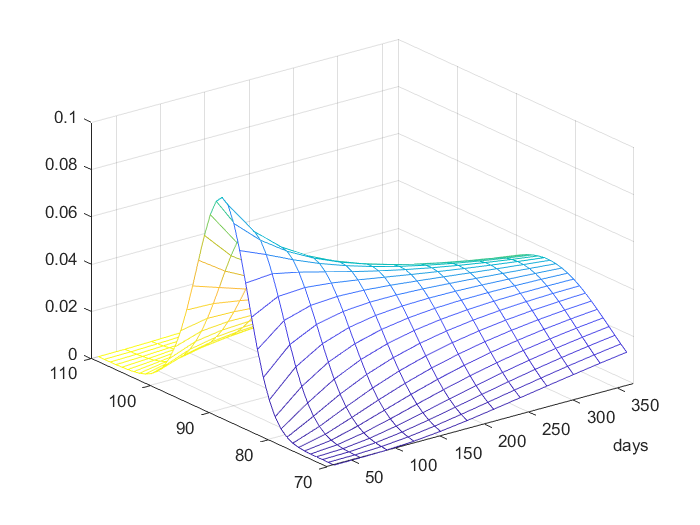

mesh(Maturities,Prices,Gamma,Delta)

FXOption.ExerciseDate

ans = datetime
   20-Dec-2283
